# Appello del 06/02/2018

## 1 Esercizio 1.

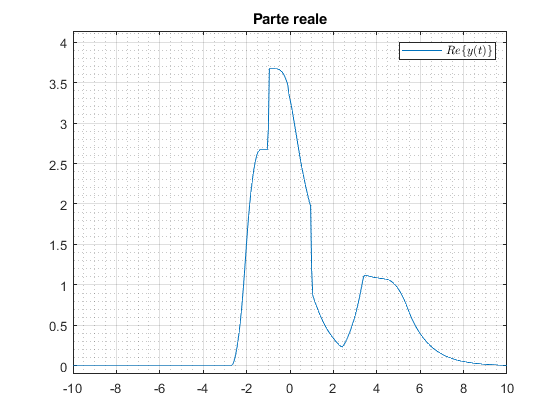

clear, close all;
t = -100:0.05:100;
s = rect(t / 2 + 1 / 2) + exp(-t) .* gradino(t);
x = 4 * tri(t * 1.5) + exp(t - 5) .* rect(t - 5);
y1 = convoluzione(t, x, s);
tau = y1(1, :);
y = y1(2, :) + abs(rect(tau / 2)).^2;
rappresentaUnSegnale(t, y, 'y(t)');
axis([-10 10 min(y) - abs(0.1 * min(y)) - 0.1 max(y) + abs(0.1 * max(y)) + 0.1]);

## 1 Esercizio 2.

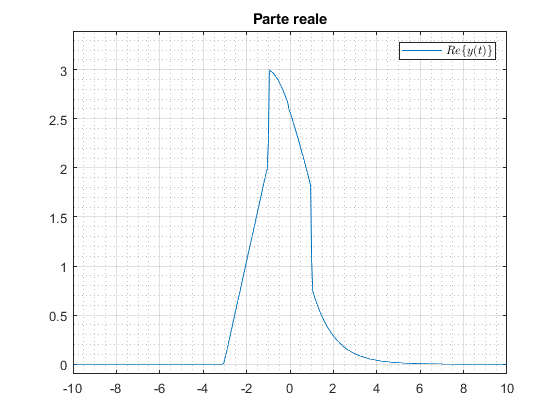

clear, close all;
t = -100:0.05:100;
s = rect(t / 2 + 1 / 2) + exp(-t) .* gradino(t);
x = rect(t / 2);
y1 = convoluzione(t, x, s);
tau = y1(1, :);
y = y1(2, :) + abs(rect(tau / 2)).^2;
rappresentaUnSegnale(t, y, 'y(t)');
axis([-10 10 min(y) - abs(0.1 * min(y)) - 0.1 max(y) + abs(0.1 * max(y)) + 0.1]);

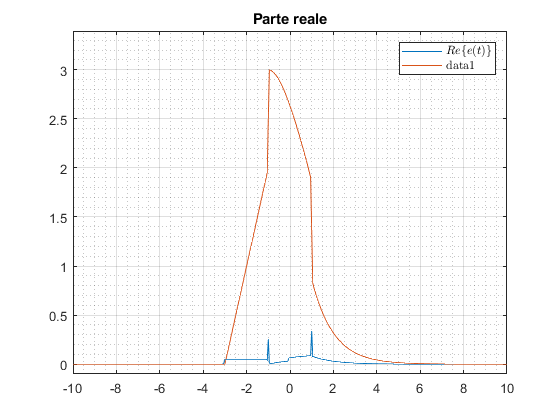

y_analitico = 2 * tri(t / 2 + 1 / 2) + rect(t / 2) + (1 - exp(-t - 1)) .* rect(t / 2) + (exp(-t + 1) - exp(-t - 1)) .* gradino(t - 1);
err_y_y_analitico = abs(y - y_analitico);
rappresentaUnSegnale(t, err_y_y_analitico, 'e(t)');
axis([-10 10 min(y) - abs(0.1 * min(y)) - 0.1 max(y) + abs(0.1 * max(y)) + 0.1]);
hold on, plot(t, y_analitico);

## 1 Esercizio 3.

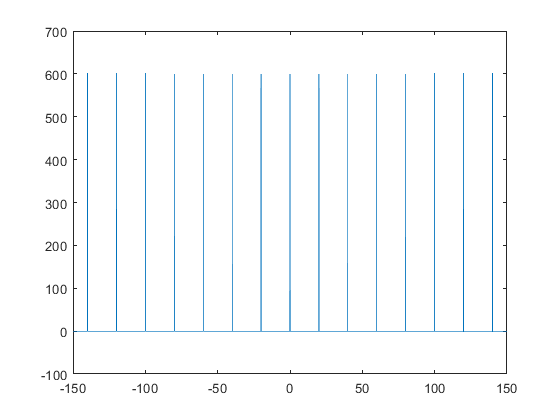

clear;
close all;
t = -100:0.05:100;
f = -150:0.05:150;
f_0 = 0;
s = rect(t / 2 + 1 / 2) + exp(-t) .* gradino(t);
S = trasformataDiFourier(t, s, f);
x = cos(2 * pi * f_0 * t);
X = trasformataDiFourier(t, x, f);
Y = X .* S;
figure, plot(f, Y);

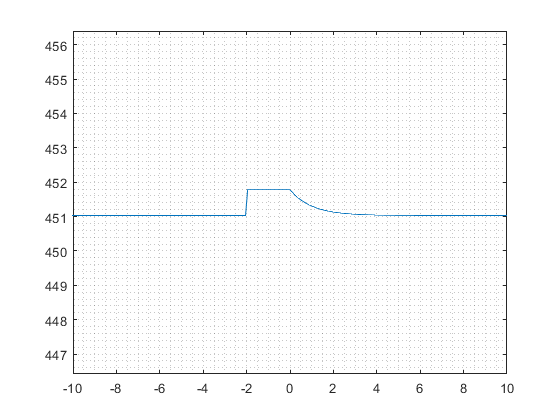

y = antitrasformataDiFourier(f, Y, t) + abs(x).^2;
figure, plot(t, real(y)), grid minor, axis([-10 10 (min(real(y)) - abs(0.01 * min(real(y))) - 0.1) (max(real(y)) + abs(0.01 * max(real(y))) + 0.1)]);

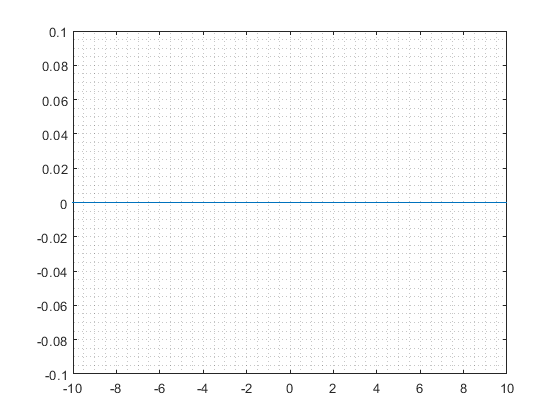

figure, plot(t, imag(y)), grid minor, axis([-10 10 min(imag(y)) - abs(0.01 * min(imag(y))) - 0.1 max(imag(y)) + abs(0.01 * max(imag(y))) + 0.1])